clear all
close all

addpath('classes')

### Simulation

dt = 0.5;
t_end = 25;
t = 0:dt:t_end;

x0 = [1;1;0];


robot_num = 3;
robot_set = repmat(Robot_w_dist_JLATT.empty, 1, robot_num);

sensor_variances    = [0.3; 0.3; 0.3];   %  variances = [v_abs; v_r; v_t]
sensor_limits       = [3; 3];            %  max_distances = [max_z_r; max_z_t]
sensor_prob         = [1; 1];
sensor_data         = {sensor_variances; sensor_limits; sensor_prob};

max_connection_distance = 2;
link_probabilities = [1; 1];          %  [abs_message_prob; rel_message_prob]
connection_data = {max_connection_distance; link_probabilities};

e_var0 = 0.2;       % initial estimated error from the true position
process_var = 0.1;  % varaince of the process white noise
stat_data = {e_var0; process_var};

for j = 1:robot_num
    x0 = [  -1 + 2*rand;
            -1 + 2*rand;
            -pi + 2*pi*rand;];

    robot_set(j) =  Robot_w_dist_JLATT(x0,j,sensor_data,connection_data, stat_data);
end

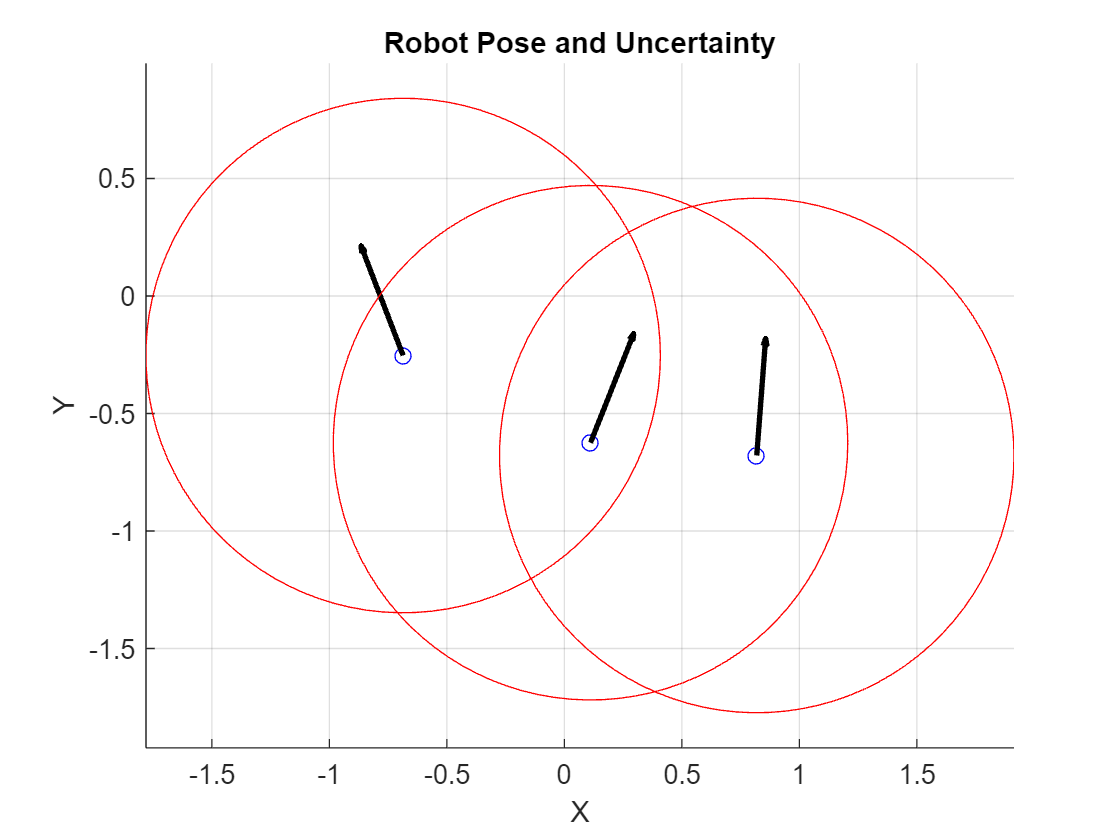


figure;
hold on;

for j = 1:robot_num 
    robot_set(j).draw_estimate()
end

% Formatting the plot
axis equal;
grid on;
xlabel('X');
ylabel('Y');
title('Robot Pose and Uncertainty');
hold off;

### Propagate once

for j = 1:robot_num
   robot_set(j) = robot_set(j).update(dt);
end

% update robot sensor readings
for j = 1:robot_num
    robot_set(j) = robot_set(j).update_meas(robot_set,t(1));
end

% update robot communication
for j = 1:robot_num
    robot_set(j) = robot_set(j).update_com(robot_set,t(1));
end

% propagate robot
for j = 1:robot_num
    robot_set(j) = robot_set(j).propagate();
end

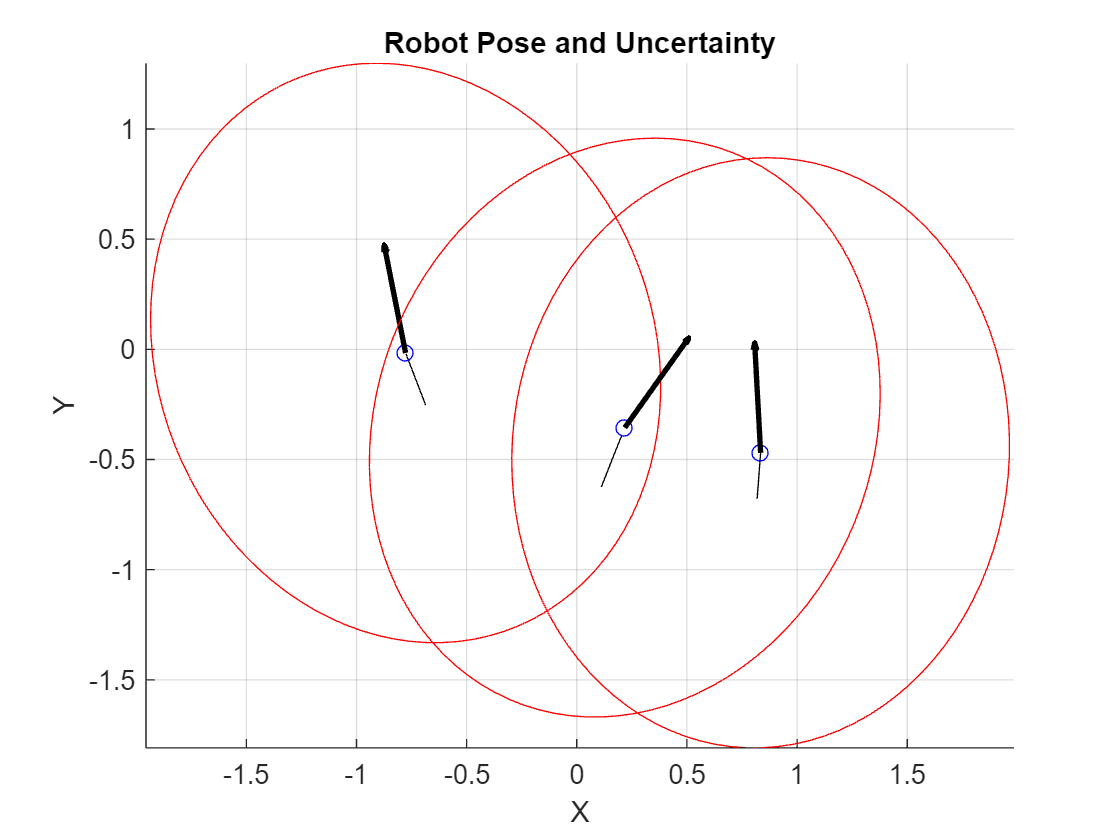

figure;
hold on;

for j = 1:robot_num 
    plot(robot_set(j).true_Path(:,1), robot_set(j).true_Path(:,2), 'k');
    robot_set(j).draw_estimate()
end

% Formatting the plot
axis equal;
grid on;
xlabel('X');
ylabel('Y');
title('Robot Pose and Uncertainty');
hold off;

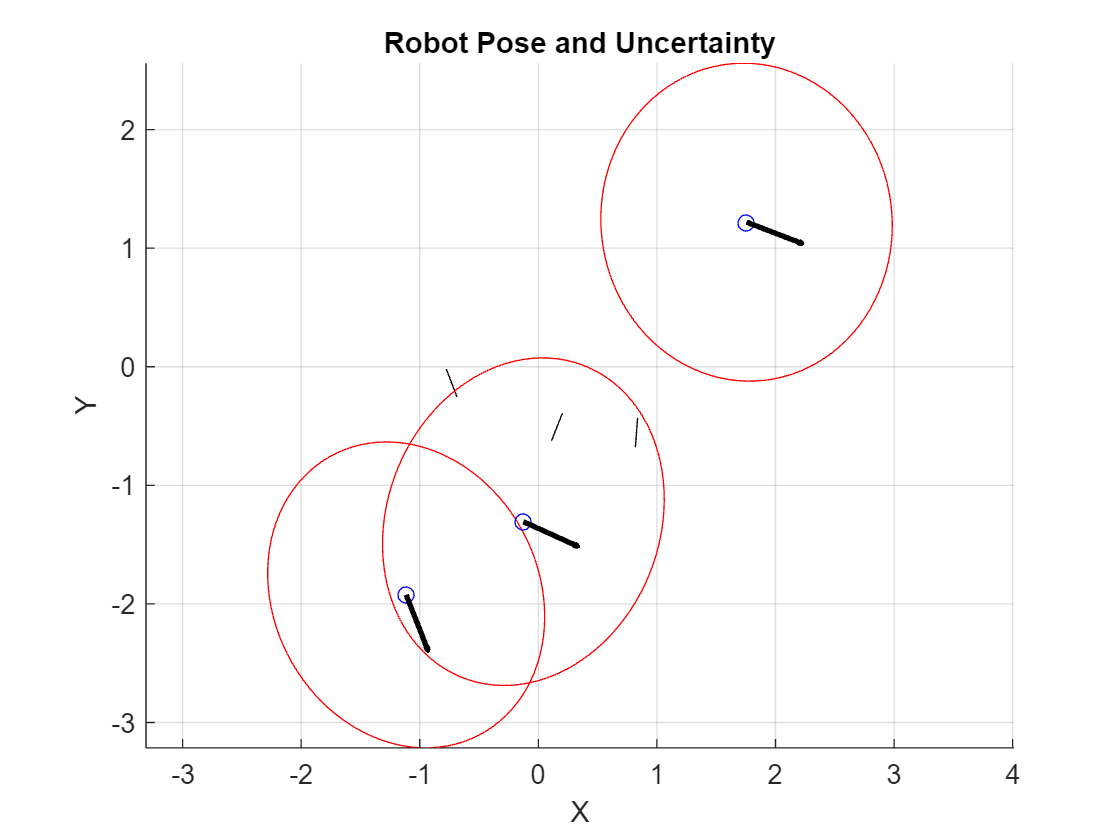


% correct with information
for j = 1:robot_num
    robot_set(j) = robot_set(j).corrections_from_com();
end

figure;
hold on;

for j = 1:robot_num 
    plot(robot_set(j).true_Path(:,1), robot_set(j).true_Path(:,2), 'k');
    robot_set(j).draw_estimate()
end

% Formatting the plot
axis equal;
grid on;
xlabel('X');
ylabel('Y');
title('Robot Pose and Uncertainty');
hold off;

### Simulation over 10 s

robot_sensor_values = [];
robot_connection_values = [];

for i = 1:length(t)
    % update robot position
    for j = 1:robot_num
        robot_set(j) = robot_set(j).update(dt);
    end

    % update robot sensor readings
    for j = 1:robot_num
        robot_set(j) = robot_set(j).update_meas(robot_set,t(i));
    end

    % update robot communication
    for j = 1:robot_num
        robot_set(j) = robot_set(j).update_com(robot_set,t(i));
    end

     % update robot communication
    for j = 1:robot_num
        robot_set(j) = robot_set(j).propagate();
    end

    % correct with information
    for j = 1:robot_num
        robot_set(j) = robot_set(j).corrections_from_com();
    end

    robot_sensor_values = [ robot_sensor_values; robot_set(1).z_r ];
    robot_connection_values = [ robot_connection_values; robot_set(1).data_rel ];
end

Error using  / 
Matrix dimensions must agree.

Error in Robot_w_dist_JLATT/corrections_from_com (line 199)
            Gamma = inv_p_hat/temp*Omega;

### Graphs

myColormap = hsv(robot_num);

figure;
hold on; axis equal;
for j = 1:robot_num
    plot(robot_set(j).true_Path(:,1), robot_set(j).true_Path(:,2), 'Color', myColormap(j,:), 'DisplayName', sprintf('Robot %d', j));
    triangle = robot_set(j).draw(1);
    patch(triangle(1,:), triangle(2,:), myColormap(j,:));
    triangle = robot_set(j).draw(length(robot_set(j).true_Path(:,1)));
    patch(triangle(1,:), triangle(2,:), myColormap(j,:));
end


xlabel('x');
ylabel('y');
title("Robot's motion over time");
legend;
% border_value = 10
% xlim([-border_value border_value])
% ylim([-border_value border_value])
grid on; hold off

figure;
hold on;

for j = 1:robot_num 
    plot(robot_set(j).true_Path(:,1), robot_set(j).true_Path(:,2), 'k');
    robot_set(j).draw_estimate()
end

% Formatting the plot
axis equal;
grid on;
xlabel('X');
ylabel('Y');
title('Robot Pose and Uncertainty');
hold off;